# REGALS analysis of MsbA time-resolved data

**The data were originally reported in:**

Josts, I.; Gao, Y.; Monteiro, D. C. F.; Niebling, S.; Nitsche, J.; Veith, K.; Graewert, T. W.; Blanchet, C. E.; Schroer, M. A.; Huse, N.; Pearson, A. R.; Svergun, D. I.; Tidow, H. *Structural Kinetics of MsbA Investigated by Stopped-Flow Time-Resolved Small-Angle X-Ray Scattering.* Structure 2020, 28 (3), 348-354.e3. [https://doi.org/10.1016/j.str.2019.12.001](https://doi.org/10.1016/j.str.2019.12.001).

**The scattering profiles were downloaded from:** SASBDB entry SASDGV5 on Aug 31, 2020. [https://www.sasbdb.org/data/SASDGV5/](https://www.sasbdb.org/data/SASDGV5/)

addpath('../matlab/'); % add REGALS code to path

## Load data

load data/MsbA_time_resolved.mat q I sigma ms name
fprintf(1,'loaded datasets:\n');

loaded datasets:


fprintf(1,'  %s\n',name{:});

  sub_20ms.dat
  sub_175ms.dat
  sub_350ms.dat
  sub_500ms.dat
  sub_700ms.dat
  sub_1090ms.dat
  sub_1500ms.dat
  sub_2100ms.dat
  sub_3150ms.dat
  sub_4200ms.dat
  sub_4800ms.dat
  sub_5950ms.dat
  sub_7700ms.dat
  sub_9450ms.dat
  sub_12000ms.dat
  sub_13500ms.dat
  sub_15000ms.dat
  sub_20000ms.dat
  sub_25000ms.dat
  sub_30000ms.dat
  sub_45000ms.dat
  sub_60000ms.dat
  sub_120000ms.dat



% remove the very low-q data (poor background subtraction?)
isincl = q>0.015;
q = q(isincl);
I = I(isincl,:);
sigma = sigma(isincl,:);

% de-jitter using polynomial smoothing
yfit = polyval(polyfit(log10(ms),sum(I,1),5),log10(ms));
f = yfit./sum(I,1);
I = I.*f;
sigma = sigma.*f;
clear yfit f

% note: the above de-jittering is optional, and can be commented out.

## Set up REGALS calculation

Each component has a concenetration and profile regularizer.

x = log10(ms); % will seek smoothness vs logarithmic time

C1 = Component(...
    Concentration(x,'smooth',...
        'xmin',1.3,...
        'xmax',5.1,...
        'isZeroAtXmin',false,...
        'isZeroAtXmax',true,...
        'Nw',31),...
    Profile(q,'realspace','dmax',70,'Nw',101));

C2 = Component(...
    Concentration(x,'smooth',...
        'xmin',1.3,...
        'xmax',5.1,...
        'isZeroAtXmin',false,...
        'isZeroAtXmax',false,...
        'Nw',31),...
    Profile(q,'realspace','dmax',62,'Nw',101));

M = Mixture([C1,C2]);


## Run REGALS

R = REGALS(I,sigma); % creat REGALS object

M.concentrationLambda = [1E-3,1E-3];
M.profileLambda = [1E11,1E11];
%M = R.autoEstimateLambda(M); % NEW! (to try, uncomment and run)

% set stopFun to return true when 100 iterations is exceeded
stopFun = @(iter,params) deal(iter >=  100,'maxIter');

updateFun = @(iter,NewMix,params,resid) ...
    fprintf(1,'%2d, x2 = %f, delta_profile = %s\n',...
    iter,params.x2,mat2str(params.delta_profile,3));

% run REGALS
[M1,params,resid] = R.run(M,stopFun,updateFun);

 1, x2 = 16.752475, delta_profile = [6.72 6.95]
 2, x2 = 0.350867, delta_profile = [33.6 32.4]
 3, x2 = 0.341523, delta_profile = [1.47 2.72]
 4, x2 = 0.338045, delta_profile = [1.11 2.01]
 5, x2 = 0.337048, delta_profile = [0.808 1.37]
 6, x2 = 0.336925, delta_profile = [0.584 0.884]
 7, x2 = 0.337032, delta_profile = [0.432 0.549]
 8, x2 = 0.337150, delta_profile = [0.334 0.331]
 9, x2 = 0.337227, delta_profile = [0.272 0.195]
10, x2 = 0.337261, delta_profile = [0.234 0.111]
11, x2 = 0.337263, delta_profile = [0.21 0.0605]
12, x2 = 0.337244, delta_profile = [0.195 0.0301]
13, x2 = 0.337211, delta_profile = [0.186 0.0119]
14, x2 = 0.337170, delta_profile = [0.181 0.00137]
15, x2 = 0.337125, delta_profile = [0.177 0.00581]
16, x2 = 0.337077, delta_profile = [0.175 0.00961]
17, x2 = 0.337028, delta_profile = [0.173 0.0119]
18, x2 = 0.336978, delta_profile = [0.172 0.0132]
19, x2 = 0.336928, delta_profile = [0.171 0.0139]
20, x2 = 0.336879, delta_profile = [0.17 0.0143]
21, x2 = 0.336829

## Extract results to plot

% P(r) functions
r1 = M1.Components(1).Profile.w;
pr1 = [0;M1.uProfile{1};0];

r2 = M1.Components(2).Profile.w;
pr2 = [0;M1.uProfile{2};0];

% Particle components (extracted)
[I1,sigma1] = M1.extractProfile(I,sigma,1);
[I2,sigma2] = M1.extractProfile(I,sigma,2);

% Concentration components (extracted)
p1 = M1.extractConcentration(I,sigma,1);
p2 = M1.extractConcentration(I,sigma,2);

% Regularized concentrations
x1 = M1.Components(1).Concentration.w;
c1 = [M1.uConcentration{1};0];
x2 = M1.Components(2).Concentration.w;
c2 = [M1.uConcentration{2}];

## Plot the end results

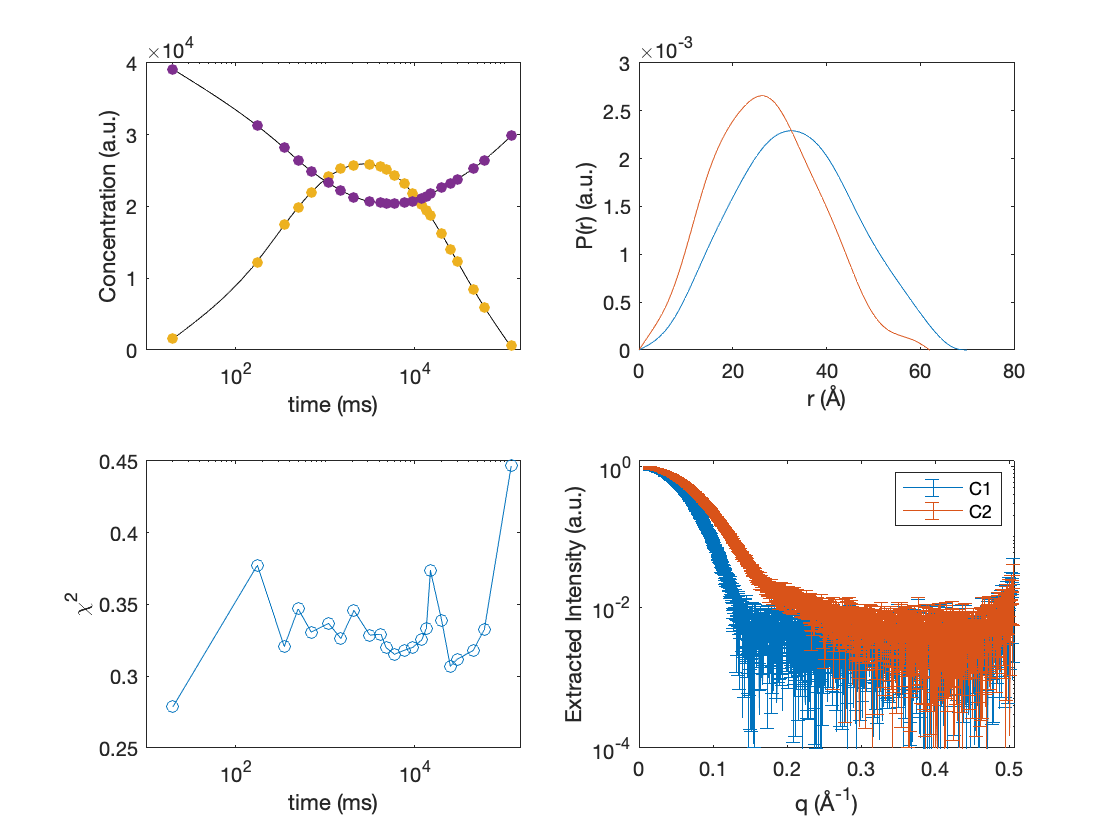

figure(1);clf;
subplot(2,2,1);
semilogx(10.^x1,c1,'k-',10.^x2,c2,'k-');hold on;
scatter(10.^x,p1,30,'filled');hold on;
scatter(10.^x,p2,30,'filled');
set(gca,'Xlim',[10,1.5E5]);xlabel('time (ms)');ylabel('Concentration (a.u.)');
subplot(2,2,2);
plot(r1,pr1,r2,pr2);xlabel('r (Å)');ylabel('P(r) (a.u.)');
subplot(2,2,3);
semilogx(10.^x,mean(resid.^2,1),'o-');
set(gca,'Xlim',[10,1.5E5]);xlabel('time (ms)');ylabel('\chi^2');
subplot(2,2,4);
errorbar(q,I1,sigma1,'DisplayName','C1');hold on;
errorbar(q,I2,sigma2,'DisplayName','C2');
set(gca,'XScale','Lin','Yscale','Log','Ylim',[1E-4,1.2E0],'XLim',[0,Inf]);
legend show; xlabel('q (Å^{-1})'); ylabel('Extracted Intensity (a.u.)');